# Webinar Text Analytics Toolbox (Oct/2019)

Apresentado por:

Alberto Y Shimahara

## **Geração de Texto com Deep Learning**

Desenvolvido por:

    - Daniel Vieira

Editado por: 

- Alberto Y Shimahara (oct/2019)

Para esta demo, requer:

- MATLAB R2019b

- Deep Learning Toolbox

- Statistics & Machine Learning Toolbox

- Text Analytics Toolbox

- Parallel Computing Toolbox

*Fonte do dataset: *[https://www.gutenberg.org/browse/scores/top](https://www.gutenberg.org/browse/scores/top) 

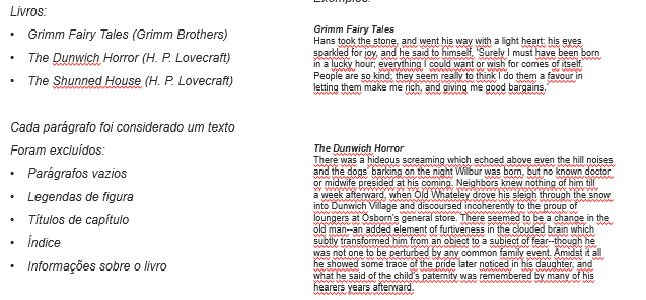

% fecha todas as janelas e limpa o workspace do MATLAB e o Command Window
close all
clear all
clc

#### Carregar os dados pré-trabalhados

O dados já foram limpos e trabalhados com o uso das funções:

- documentGenerationDatastore.m

- labeledDocumentGenerationDatastore.m

load('2booksDs.mat')

#### Parametros de Treinamento da Rede Neural

Aplicamos a mesma rede do exemplo anterior (dados da Reuters), mas com milhares de classes (1 classe por palavra)

inputSize = 1;
embeddingDimension = 300;
numWords = numel(ds.Encoding.Vocabulary);
numClasses = numWords + 1;

layers = [
    sequenceInputLayer(inputSize)
    wordEmbeddingLayer(embeddingDimension,numWords)
    lstmLayer(300)
    dropoutLayer(0.2)
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

Não separamos dados para validação e teste nesse caso, usamos todos o dados existentes para treino.


options = trainingOptions('adam', ...
    'MaxEpochs',300, ...
    'InitialLearnRate',0.01, ...
    'MiniBatchSize',4, ...
    'Shuffle','never', ...
    'Plots','training-progress', ...
    'Verbose',false);

#### Treinando a Rede

net = trainNetwork(ds,layers,options);

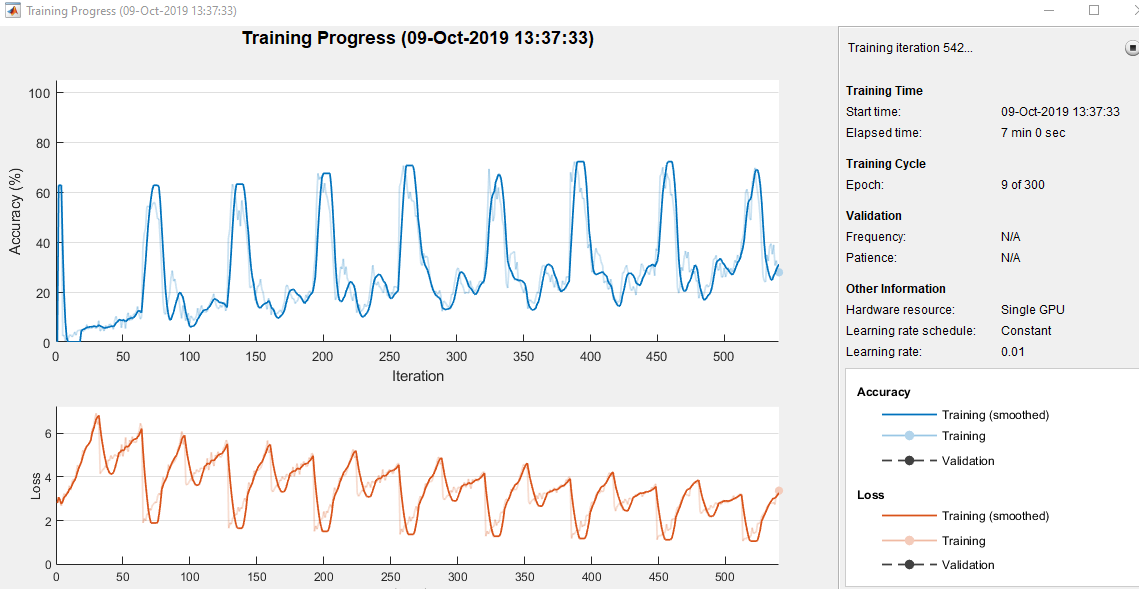

#### Gerando texto a partir da Rede Treinada

*Usa a rede treinada para calcular as probabilidades de cada palavra, dada a palavra atual (começando de *`“Grimm_Brothers"`*) e o estado da rede até o momento, e atualiza o estado*


enc = ds.Encoding;
wordIndex = word2ind(enc,"Grimm_Brothers");
vocabulary = string(net.Layers(end).Classes);

generatedText = "";
maxLength = 5000;
while strlength(generatedText) < maxLength
    % Predict the next word scores.
    % Opção "cpu" para processamento local ou "gpu" aplica GPU Nvidia com suporte a CUDA e
    % requer Parallel Computing Toolbox
    [net,wordScores] = predictAndUpdateState(net,wordIndex,'ExecutionEnvironment','cpu');
    
    % Sample the next word.
    newWord = datasample(vocabulary,1,'Weights',wordScores);
    
    % Stop predicting at the end of text.
    if newWord == "EndOfText"
        break
    end
    
    % Add the word to the generated text.
    generatedText = generatedText + " " + newWord;
    
    % Find the word index for the next input.
    wordIndex = word2ind(enc,newWord);
end


Remove espaços desnecessários gerados antes ou depois de sinais de pontuação


punctuationCharacters = ["." "," "’" ")" ":" "?" "!"];
generatedText = replace(generatedText," " + punctuationCharacters,punctuationCharacters);

punctuationCharacters = ["(" "‘"];
generatedText = replace(generatedText,punctuationCharacters + " ",punctuationCharacters)

generatedText = " After this the timbers is matted daown, and the children were in the water, and sat down together and said, ‘The queen will soon as evening, in a golden brooch, and packed the three dresses - - so he was forced to run after it. Then they turned upon him and tried to escape, but the guests seized the goose to be seen as soon as she leaves a better next time.’ And as I patted down in the floor."

#### Exempo de texto gerado conforme Conto dos Irmãos Grimm

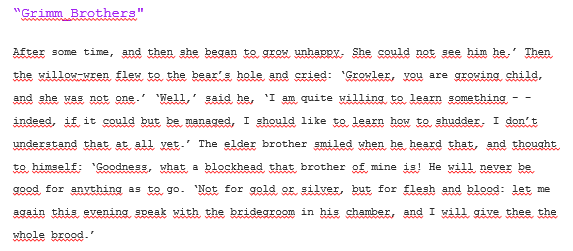

Reseta para gerar outro texto

net = resetState(net);